**Part A: Loading Input**



im = imread('holy-plate-main2.png');     % A1
imgray = rgb2gray(im);                   % A2
imbin = imbinarize(imgray);              % A3
im = edge(imgray, 'prewitt');            % A4

A1: Load Image

A2: Converts RGB to Grayscale Image

A3: Converts image to a matrix consisting of binary numbers.

A4: Detects edge. Does it mean the sides of the picture?

**Part B: Filtering and Displaying the Image**

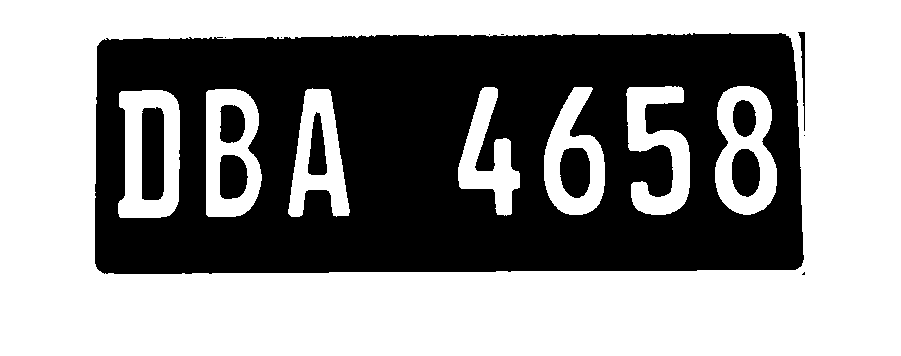


% Below steps are to find location of number plate
Iprops=regionprops(im,'BoundingBox','Area', 'Image'); 
area = Iprops.Area;
count = numel(Iprops);
maxa= area;
boundingBox = Iprops.BoundingBox;
for i=1:count
   if maxa<Iprops(i).Area
      maxa=Iprops(i).Area;
      boundingBox = Iprops(i).BoundingBox;
   end
end   

im = imcrop(imbin, boundingBox);
im = bwareaopen(~im, 500);
 [h, w] = size(im);

imshow(im);

**C. Detecting and Determining the Characters Presented in the Plate Number**

Iprops=regionprops(im,'BoundingBox','Area', 'Image');
count = numel(Iprops);
noPlate=[];
for i=1:count                            % Cropping/Detection
   ow = length(Iprops(i).Image(1,:));
   oh = length(Iprops(i).Image(:,1));
   if ow<(h/2) && oh>(h/3)
       letter=readLetter(Iprops(i).Image)
       noPlate=[noPlate letter];
   end
end

  1×0 empty double row vector



letter = 'n'

  1×0 empty double row vector



letter = 'n'

  1×0 empty double row vector



letter = 'n'

  1×0 empty double row vector



letter = 'n'

  1×0 empty double row vector



letter = 'n'

  1×0 empty double row vector



letter = 'n'

  1×0 empty double row vector



letter = 'n'

**D. Database**

% Setting-Up Alphanumeric Template
% Alphabet

A = imread('Alphanumeric/A.bmp');
B = imread('Alphanumeric/B.bmp');
C = imread('Alphanumeric/C.bmp');
D = imread('Alphanumeric/D.bmp');
E = imread('Alphanumeric/E.bmp');
F = imread('Alphanumeric/F.bmp');
G = imread('Alphanumeric/G.bmp');
H = imread('Alphanumeric/H.bmp');
I = imread('Alphanumeric/I.bmp');
J = imread('Alphanumeric/J.bmp');
K = imread('Alphanumeric/K.bmp');
L = imread('Alphanumeric/L.bmp');
M = imread('Alphanumeric/M.bmp');
N = imread('Alphanumeric/N.bmp');
O = imread('Alphanumeric/O.bmp');
P = imread('Alphanumeric/P.bmp');
Q = imread('Alphanumeric/Q.bmp');
R = imread('Alphanumeric/R.bmp');
S = imread('Alphanumeric/S.bmp');
T = imread('Alphanumeric/T.bmp');
U = imread('Alphanumeric/U.bmp');
V = imread('Alphanumeric/V.bmp');
W = imread('Alphanumeric/W.bmp');
X = imread('Alphanumeric/X.bmp');
Y = imread('Alphanumeric/Y.bmp');
Z = imread('Alphanumeric/Z.bmp');

% Numbers
ZERO = imread('Alphanumeric/0.bmp');
ONE = imread('Alphanumeric/1.bmp');
TWO = imread('Alphanumeric/2.bmp');
THREE = imread('Alphanumeric/3.bmp');
FOUR = imread('Alphanumeric/4.bmp');
FIVE = imread('Alphanumeric/5.bmp');
SIX = imread('Alphanumeric/6.bmp');
SEVEN = imread('Alphanumeric/7.bmp');
EIGHT = imread('Alphanumeric/8.bmp');
NINE = imread('Alphanumeric/9.bmp');

let = [A B C D E F G H I J K L M N O P Q R S T U V W X Y Z];
num = [ZERO ONE TWO THREE FOUR FIVE SIX SEVEN EIGHT NINE];

temp = [let num];          % Will run over and over again.
save('temp', 'temp');


**E. Letter Detection (Correlation)**

function let = readLetter(pic)    % What does "pic" represent? Should it be "im" instead?

load temp

pic = imresize(pic, [45 20]);     % E1
rec = [ ];                        % E2                                

% > pic needs to have the same size compare to what?
% > Changing [45 20] to [900 600] "Size of Used Image" does not solve the
% problem in which all output values are n.

% Character Recognition
for n=1:length(temp)
    correlate = corr2(imresize(temp(1,n),[45 20]), pic);    % Correlation does not work
    rec = [rec correlate];
end

index = find(rec == max(rec));    % Determines the max characters due to detection.
display(find(rec == max(rec)))

% Alphabet List
if isequal(index,1) || isequal(index,2)
    let = 'A';
elseif isequal(index,3) || isequal(index,4)
    let = 'B';
elseif index == 5
    let = 'C';
elseif isequal(index,6) || isequal(index,7)
    let = 'D';
elseif index == 8
    let = 'E';
elseif index == 9
    let = 'F';
elseif index == 10
    let = 'G';
elseif index == 11
    let = 'H';
elseif index == 12
    let = 'I';
elseif index == 13
    let = 'J';
elseif index == 14
    let = 'K';
elseif index == 15
    let = 'L';
elseif index == 16
    let = 'M';
elseif index == 17
    let = 'N';
elseif isequal(index,18) || isequal(index,19)
    let = 'O';
elseif isequal(index,20) || isequal(index,21)
    let = 'P';
elseif isequal(index,22) || isequal(index,23)
    let = 'Q';
elseif isequal(index,24) || isequal(index,25)
    let = 'R';
elseif index == 26
    let = 'S';
elseif index == 27
    let = 'T';
elseif index == 28
    let = 'U';
elseif index == 29
    let = 'V';
elseif index == 30
    let = 'W';
elseif index == 31
    let = 'X';
elseif index == 32
    let = 'Y';
elseif index == 33
    let = 'Z';

% Number Listings
elseif index == 34
    let = '1';
elseif index == 35
    let = '2';
elseif index == 36
    let = '3';
elseif isequal(index,37) || isequal(index,38)
    let = '4';
elseif index == 39
    let = '5';
elseif isequal(index,40) || isequal(index,41) || isequal(index,42)
    let = '6';
elseif index == 43
    let = '7';
elseif isequal(index,44) || isequal(index,45)
    let = '8';
elseif isequal(index,46) || isequal(index,47) || isequal(index,48)
    let = '9';
else
    let = 'n';     % ERROR: Output always goes here, skipping anything else before it.
end
end

E1. Dimensions (adjusting the number of pixels).

E2. Empty container ready to be filled up (Code will tell what characters are present in the plate number and fill the container  up).

E3. What does [45 20] mean? Is it changing the size of the picture?

E4. pic needs to have the same size compared to what?

E5. Changing [45 20] to [900 600] "size of the chosen picture" does not solve the problem in which all output values are still n.